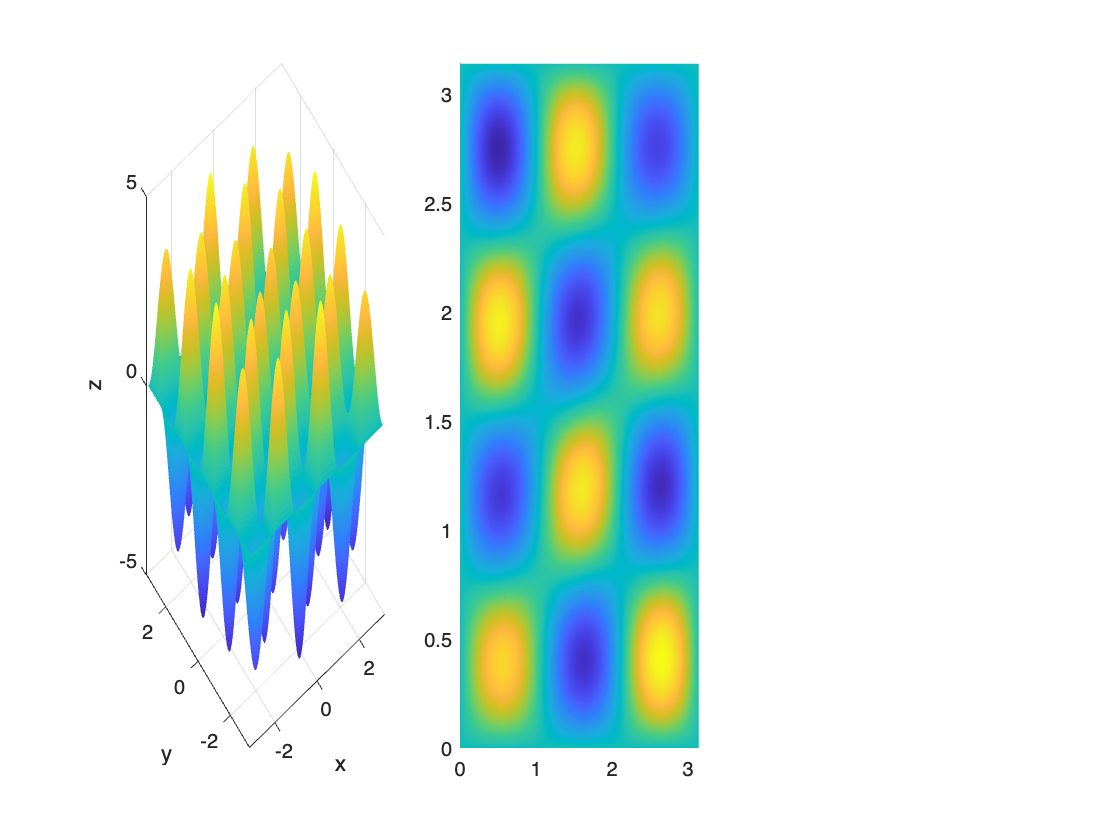

%define dimensions of square membrane
l = pi;
%define initial velocity
v = 1;

%constants
m =3 ; 
n =4;
kx = m*pi/l;
ky = n*pi/l;
A =4;
B =1;
    
w = v * sqrt(kx^2+ky^2);

%characteristic frequency
%gamma_mn = c*pi*sqrt((m^2/length^2)+(n^2/width^2));

%constants = [m, n, A, B]

 
%making the MATLAB mesh
[X, Y] = meshgrid(-l:0.01:l);

%making the wave function simulation
t_final = 2;
for t = 0:0.05:t_final
   
    %2D wave equation
    Z = (A*sin(X*kx).*sin(Y*ky))+(B*sin(kx*Y).*sin(ky*X)*sin(w*t));

    %regular view
    %figure(f1);
    subplot(1,3,1)
    p1 = surf(X, Y, Z, "EdgeColor","none");
    xlabel('x')
    ylabel('y')
    zlabel('z')
    axis ([-3.2 3.2 -3.2 3.2 -5 5]);
    
    %top down view
    %figure(f2);
    subplot(1,3,2)
    p2 = surf(X, Y, Z, "EdgeColor","none");
    view(0, 90);
    axis([0 pi 0 pi]);
    
    hold on
    pause(0.01);
    
    if(t ~= t_final)
       delete(p1);
       delete(p2);
    end
end